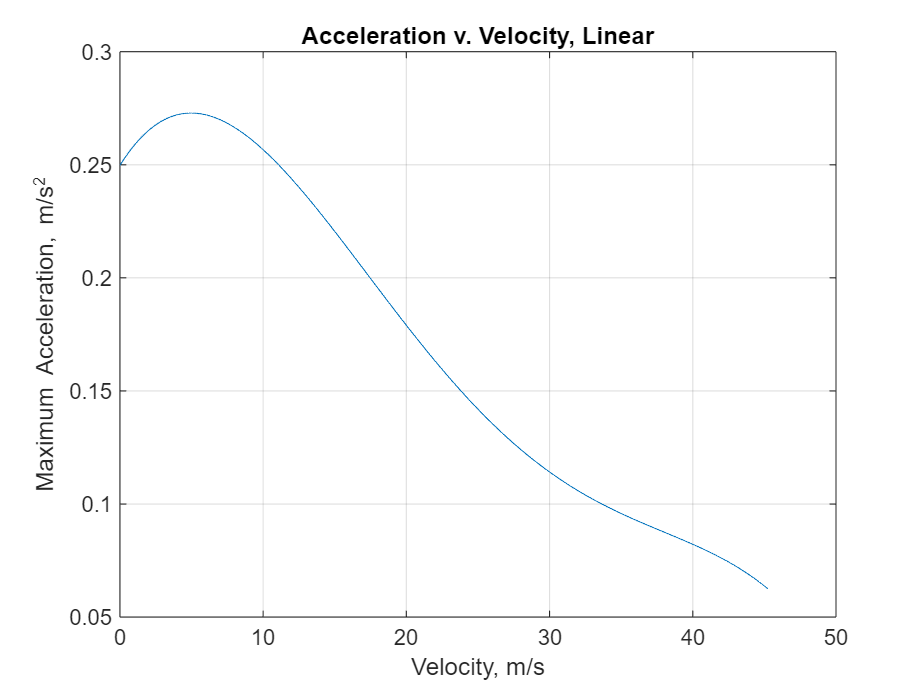

derate = 0.9; %estimated efficiency
speedFunc = @(x) (-1.039*10^-10*x.^4+3.044*10^-7*x.^3-0.0002872*x.^2+0.06088*x+39.96)*derate/60 %rpm to torque, X/Y Drive

massX = 4;
pulleyR = 0.006; %meters, drive pulley

torque2force = @(x) x/(100*pulleyR);
velo2rpm = @(x) x/(2*pulleyR*pi);
velo2torque = @(x) speedFunc(velo2rpm(x));
velo2acc = @(x) torque2force(velo2torque(x))/massX; %input velocity, m/s, outputs maximum acceleration of massX
rotationLinear = @(x) 0.012*pi*x; %x = rpm, output is m/s
rpmRange = linspace(0, 1200, 1200);

targetSpeed = 0.2; %m/s
targetDist = 0.3; %m
maxAccel = 0.15; %m/s^2

V = targetSpeed;
D = targetDist;
A = maxAccel;
t_end = (D/V) + (V/A);
time2pos = linspace(0, t_end, 1000);

function v = trapVelocity(t, v_target, dist, accel)
    t_accel = v_target / accel;
    d_accel = 0.5 * accel * t_accel^2;
    
    if (2 * d_accel) > dist
        error('Distance is too short to reach target velocity.');
    end
    
    t_cruise = (dist - 2 * d_accel) / v_target;
    
    time1 = t_accel;
    time2 = t_accel + t_cruise;
    time3 = time2 + t_accel;

    % Pre-allocate velocity array with zeros
    v = zeros(size(t));

    % Phase 1: Accel
    v(t >= 0 & t < time1) = accel * t(t >= 0 & t < time1);
    
    % Phase 2: Cruise
    v(t >= time1 & t < time2) = v_target;
    
    % Phase 3: Decel
    v(t >= time2 & t <= time3) = v_target - accel * (t(t >= time2 & t <= time3) - time2);
end

trapAccel = @(v, v_tar, a_max) (v < v_tar) * a_max + (v >= v_tar) * 0;

figure(1);
plot(rotationLinear(rpmRange), velo2acc(rotationLinear(rpmRange)));
xlabel("Velocity, m/s");
ylabel("Maximum Acceleration, m/s^2")
grid on;
title("Acceleration v. Velocity, Linear")

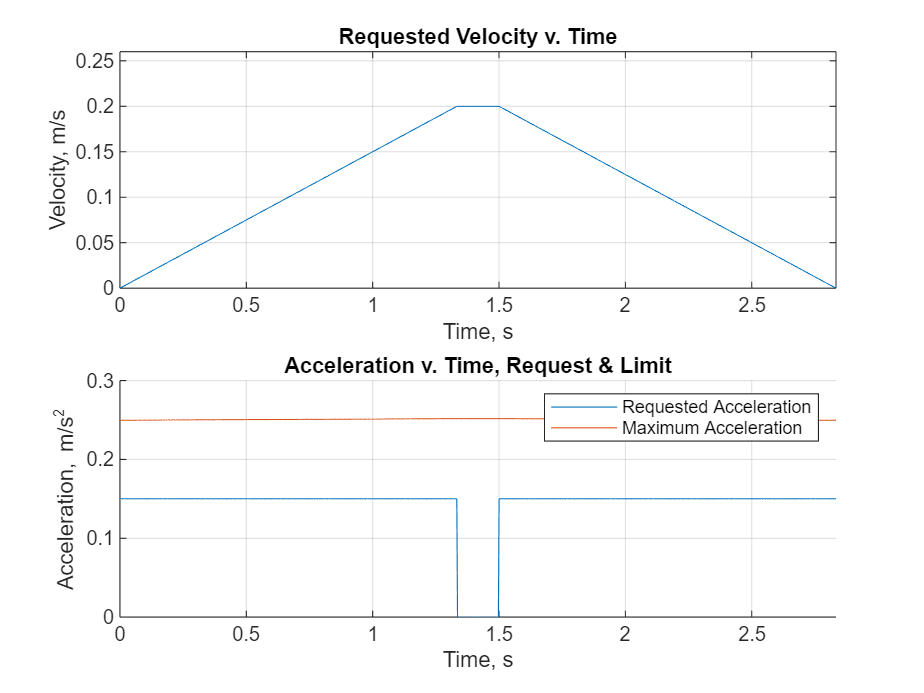



figure(3);
subplot(2, 1, 1);
plot(time2pos, trapVelocity(time2pos, V, D, A))
xlim([0 t_end])
ylim([0 V+0.3*V])
ylabel("Velocity, m/s");
xlabel("Time, s")
grid on;
title("Requested Velocity v. Time");

subplot(2, 1, 2);
hold on;
plot(time2pos, trapAccel(trapVelocity(time2pos, V, D, A), V, A));
plot(time2pos, velo2acc(trapVelocity(time2pos, V, D, A)));
legend("Requested Acceleration", "Maximum Acceleration");
grid on;
ylabel("Acceleration, m/s^2");
xlabel("Time, s");
xlim([0, t_end]);
title("Acceleration v. Time, Request & Limit")


fprintf("Time to Target Position %d millimeters: %.3f seconds", D*1000, t_end)

Time to Target Position 300 millimeters: 2.833 seconds

fprintf("Target Parameters: %d Travel Distance (mm), %d Acceleration Maximum (mm/s^2), %.2f Target Velocity (m/s)", D*1000, V*1000, A);

Target Parameters: 300 Travel Distance (mm), 200 Acceleration Maximum (mm/s^2), 0.15 Target Velocity (m/s)